# Import images

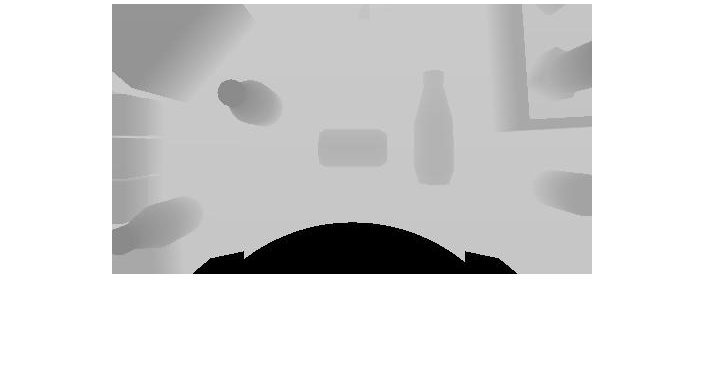

original_depth_img = imread('imgs/depth.jpg');   % Depth sensor 
original_rgb_img = imread('imgs/rgb.jpg');       % RGB Camera 

imshow(original_depth_img)

%% Low Pass Filter
sigma = 1.2; % SD

rgb_img = imgaussfilt(original_rgb_img, sigma);
depth_img = imgaussfilt(original_depth_img, sigma);

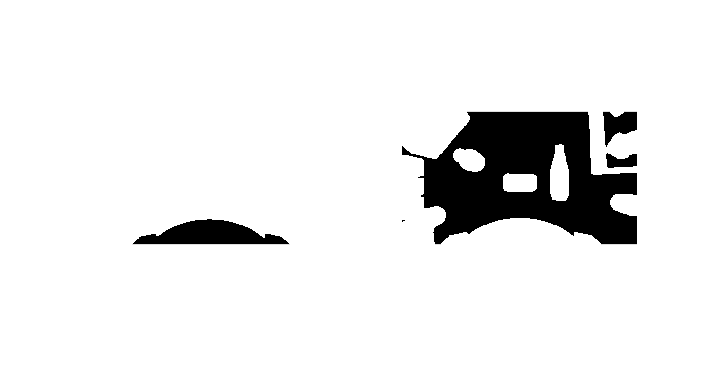

% Binarize image 
bw_1 = imbinarize(depth_img, 0.25); 

inv = 255 - depth_img; 
bw_2 = imbinarize(inv, 0.25); 
% inver image 
% 0.25 - 0.75

subplot(1,2 ,1)
imshow(bw_1)
subplot(1,2 ,2)
imshow(bw_2)

## Binary Range In

Take the binary thresholds mask and define a RageIn from superposition

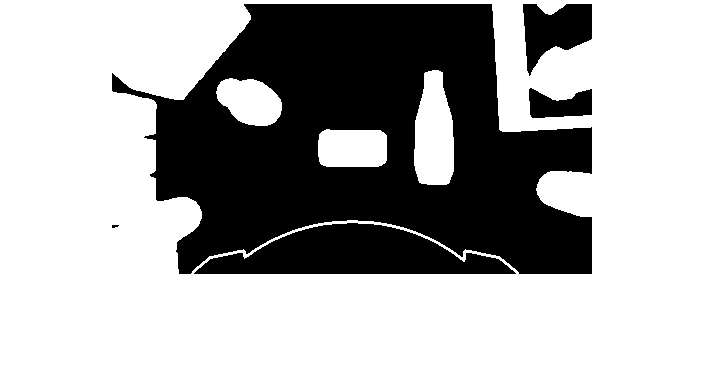

figure; 
bw = bw_1 .* bw_2; 
title("Soperposition Mask");
imshow(bw); 

## Clean the image

Apply morphological transformation to smooth the masks

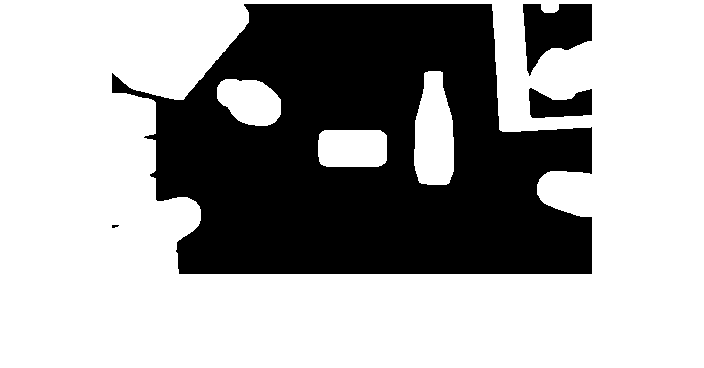

s = strel("square", 10); 

bw = imerode(bw, s); 
bw = imdilate(bw, s); 

imshow(bw)